# EE-414 Speech Processing Lab

#  Lab-8

## Introduction:

We know that the output of a system is characterised by its input excitation and response of the system. Convolution of these two leads to the output of the system. To get back the individual components, we have to use deconvolution. There are various cases for deconvolution i.e. when only input excitation is known or when only the response is known or when both response and input excitation is unknown. In the last case, we will use cepstral analysis to get both the input excitation and response of the system.

We know that speech is composed of vocal tract system information and excitation source information and it is important to separate these two components to do our analysis, so cepstral analysis will aid us to get these two components. 

Speech signals are made by convolution of the excitation source (for voiced: periodic impulse, for unvoiced: random noise) and response of the vocal tract system:

In frequency domain, this leads to multiplication i.e. :

Cepstral analysis is used for transforming the multiplied source and system components in the frequency domain to linear combination of the two components in the cepstral domain so that deconvolution will take place easier.

## Aim 

#### ● To understand motivation behind Cepstral Analysis of speech 

#### ● To understand basic Cepstral Analysis approach 

#### ● To perform vocal tract and source information separation by Cepstral Analysis 

#### ● To understand liftering concept in cepstral Analysis 

#### ● To develop a pitch determination method by Cepstral analysis. 

#### ● To develop a formant information determination method by Cepstral analysis.

Spectrogram and Waveform of "Speech Signal" from wavesurfer

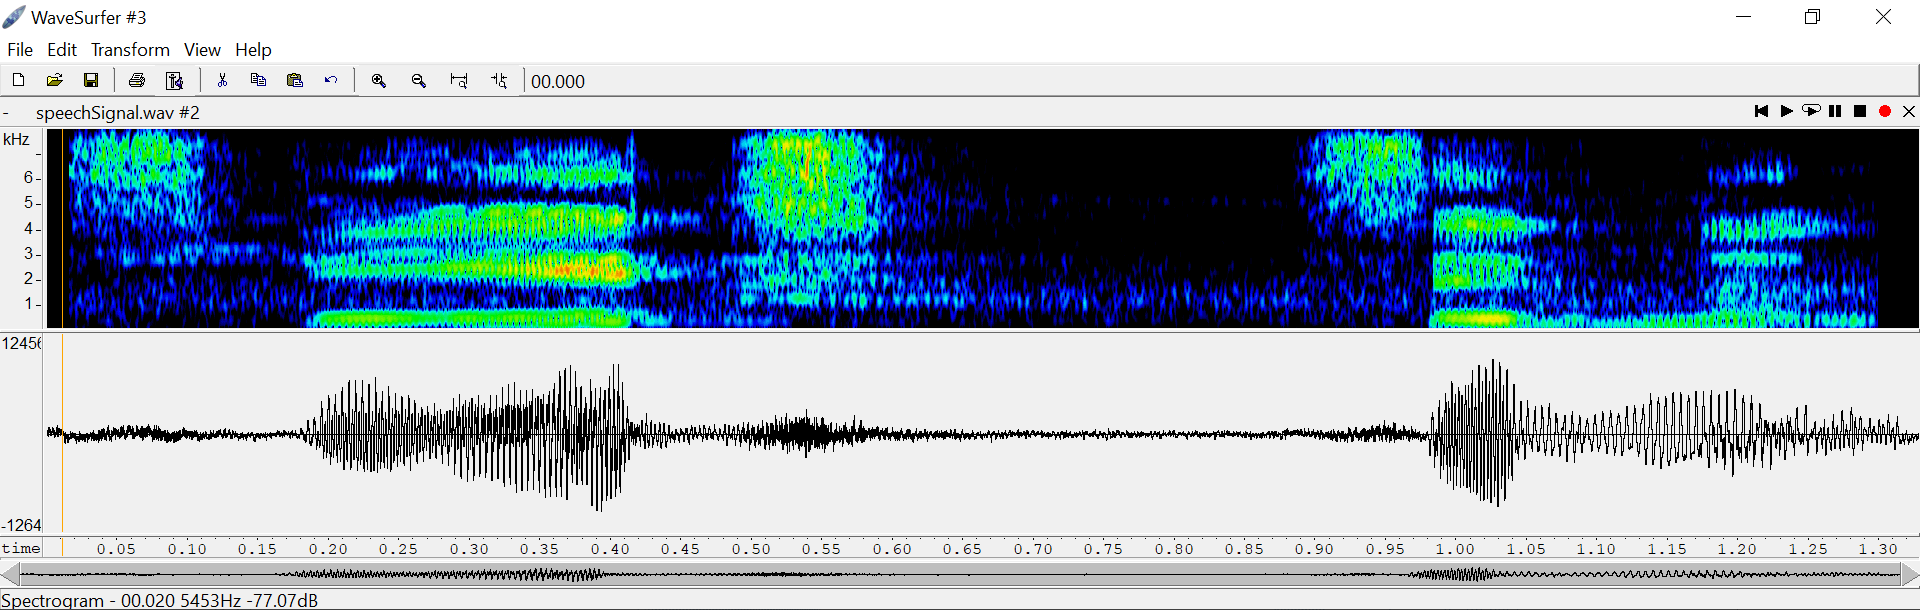

Record (16kHz, 16bit) the word “speech signal”; truncate long silence regions. 

### A. Fundamentals of cepstral analysis of speech

a. Select a frame (20 ms long) at the centre of a voiced segment. Plot the time waveform, the log-magnitude spectrum, and the cepstrum.. 

b. Repeat the above for an unvoiced segment. 

c. Write the procedure to determine whether the segment is voiced/unvoiced by inspecting the cepstrum. Apply this procedure to the two segments (in a and b). 

#### Theory:

To split the multiplication in frequency domain to linear combination, we will apply log to get :

So we can split the excitation source and vocal tract info. Now by applying IDFT, we get to the quefrency domain/cepstral domain (which is slightly different from the conventional time domain) i.e. we get the cepstrum of the signal as follows:

In the quefrency domain the variations in the lower quefrency region (near 0 axis) is due to vocal tract characteristics and the fast varying nature of the cepstrum towards the upper quefrency region represents the excitation characteristics. 

#### Procedure:

We take the audio sample and select the voiced part (ee) and unvoiced part (ch) and take a 20ms long frame at the centre of these sounds. Then we apply hamming window to these sounds and plot the waveform and spectrum. We then get the cepstrum by applying ifft on the log magnitude spectrum. We do these steps for voiced and unvoiced sounds "ee" and "ch" and observe the plots.

Block diagram for calculating the cepstrum:

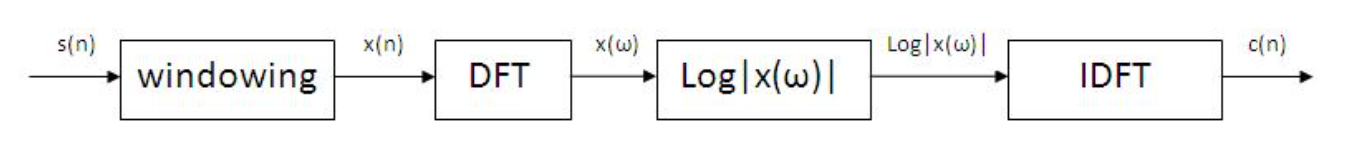

#### **Code:**

**a.**

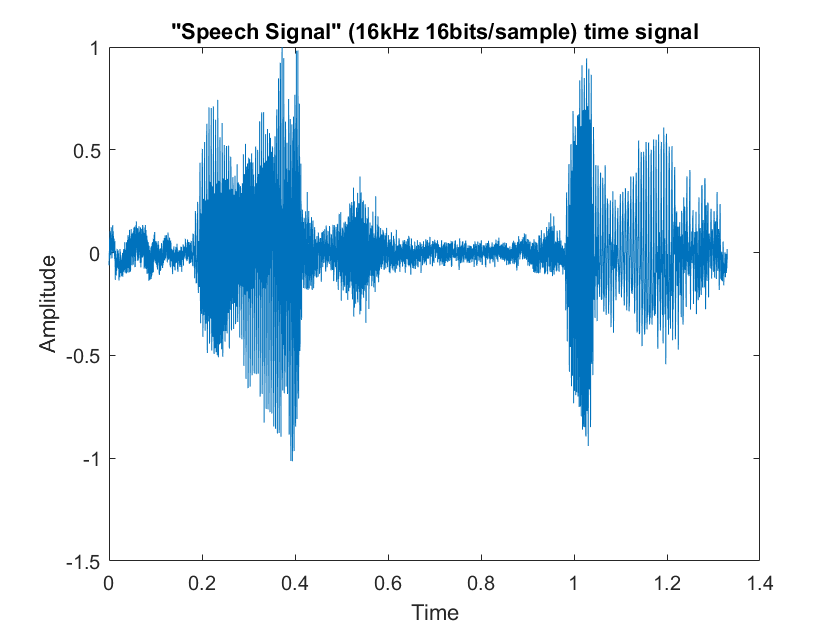

close all; clc; clear all;

[y,fs]=audioread('speechSignal.wav'); 
% sound(y, fs);

sound_sample = y(:,1); % Taking left channel
sound_sample = sound_sample./max(sound_sample); % Normalizing

% "Speech Signal" 
plot_time_signal(sound_sample, fs, '"Speech Signal" (16kHz 16bits/sample) time signal'); 

% getting s_n
voiced_part = sound_sample(round(0.30*fs):round(0.40*fs)); % ee 
voiced_frame = voiced_part(round(length(voiced_part)/2) - 0.010*fs:round(length(voiced_part)/2) + 0.010*fs - 1);

% getting x_n by windowing
win = dsp.Window("Hamming");
voiced_hamm = win(voiced_frame);

% plotting for voiced frame
subplot(321)
plot_time_signal(voiced_hamm, fs, 'voiced frame waveform "ee" ');
subplot(323)
plot_freq_spectrum(voiced_hamm, fs, 'Log Magnitude spectrum of voiced frame "ee"', 'log');

% getting c_n i.e. cepstrum 
cepst_voiced = ifft(log(abs(fftshift(fft(voiced_hamm)))));
cepst_voiced = cepst_voiced(1:round(length(cepst_voiced)/2));

% plotting cepstrum
subplot(325)
plot(cepst_voiced);
title('cepstrum of voiced frame "ee"'); xlabel('quefrency/samples'); ylabel('amplitude');

#### **b.**

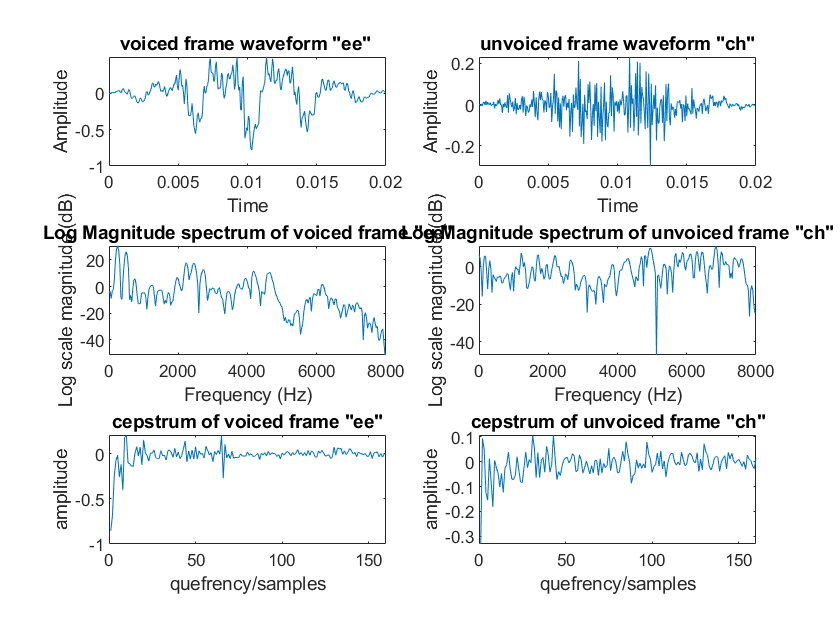

% getting s_n
unvoiced_part = sound_sample(round(0.5*fs):round(0.6*fs)); % ch
unvoiced_frame = unvoiced_part(round(length(unvoiced_part)/2 - 0.010*fs):round(length(unvoiced_part)/2 + 0.010*fs)-1);

% getting x_n by windowing
win = dsp.Window("Hamming");
unvoiced_hamm = win(unvoiced_frame);

% plotting for unvoiced frame
subplot(322)
plot_time_signal(unvoiced_hamm, fs, 'unvoiced frame waveform "ch"');
subplot(324)
plot_freq_spectrum(unvoiced_hamm, fs, 'Log Magnitude spectrum of unvoiced frame "ch"', 'log');

% getting c_n i.e. cepstrum 
cepst_unvoiced = ifft(log(abs(fftshift(fft(unvoiced_hamm)))));
cepst_unvoiced = cepst_unvoiced(1:round(length(cepst_unvoiced)/2));

% plotting cepstrum
subplot(326)
plot(cepst_unvoiced);
title('cepstrum of unvoiced frame "ch"'); xlabel('quefrency/samples'); ylabel('amplitude');

       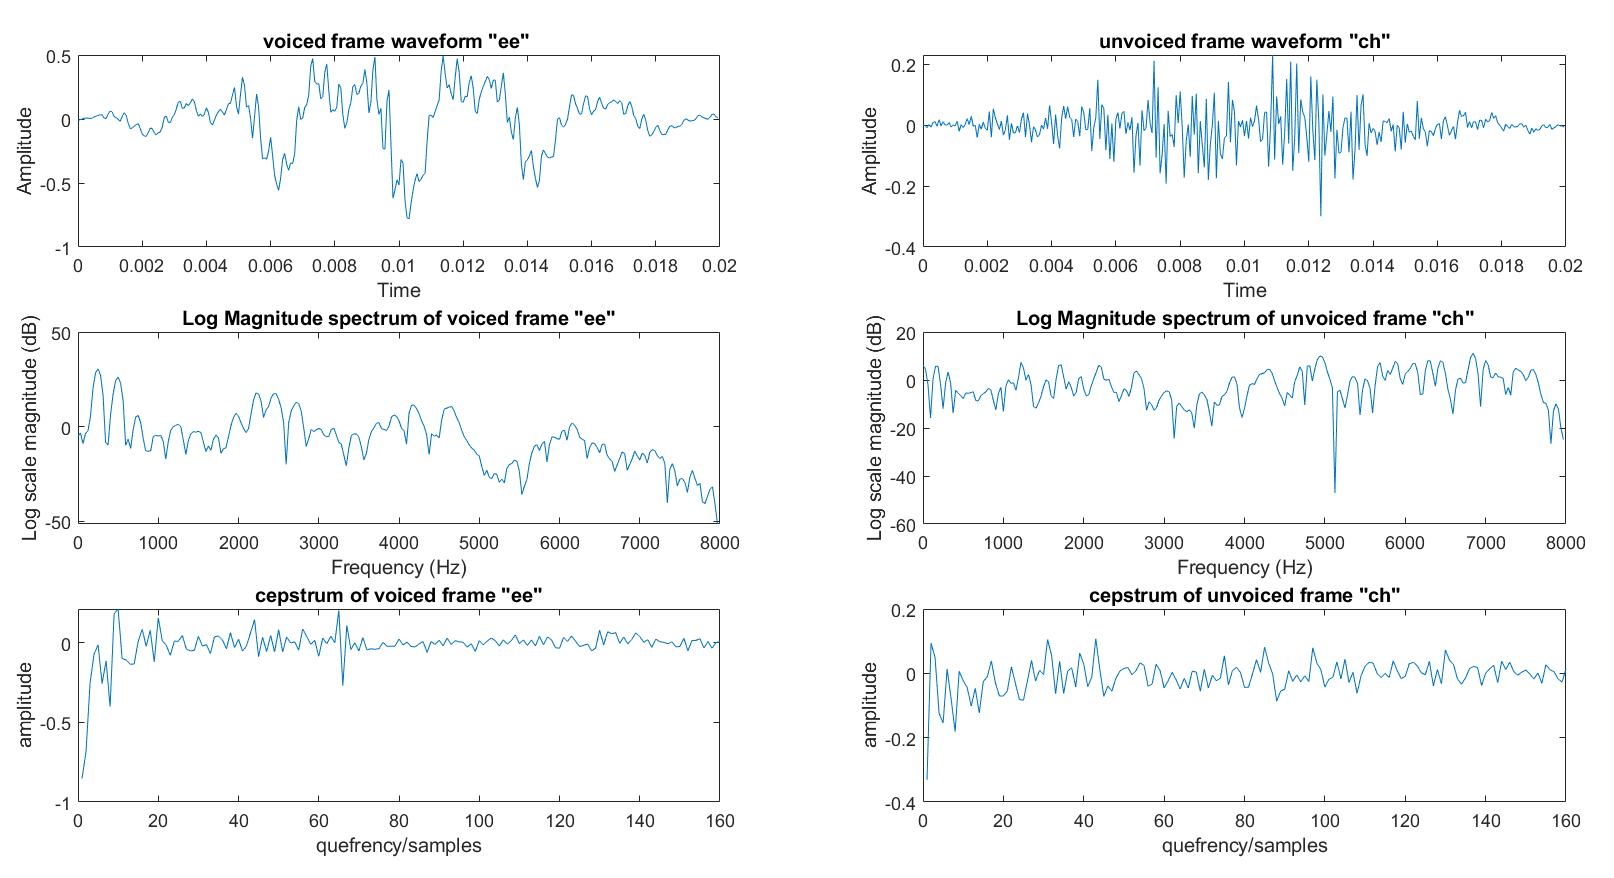

**c.**

**Procedure/Observations:**

We see that for the cepstrum of voiced sound, we see sharp peaks until a certain number of samples (here around 70 samples) whereas for unvoiced we see sharp peaks throughout the cepstrum. The peaks are more random like in nature for the case of unvoiced sounds. If we observe a distinguishable peak after 15-20 coefficients, we can say that the cepstrum belongs to a voiced sound, otherwise it belongs to unvoiced sound. We can use this fact to distinguish between unvoiced and voice cepstrum

### B. Liftering: 

a. Extract the deconvolved vocal tract component and excitation component from the cepstrum by liftering. 

b. Write about how you used Low-Time Liftering and High-Time Liftering for extracting the above components. 

#### Theory:

To extract the vocal tract information and the excitation source, we will apply low time liftering and high time liftering in the quefrency domain respectively. We do liftering by multiplying a rectangular window to the entire signal and thus we get the part of the cepstrum that represent the vocal tract and excitation source.

We know that the vocal tract information is slowly varying in nature hence we will apply low time liftering to get the 1st few cepstral coefficients, and we know the excitation source is rapidly varying in nature thus can be obtained by applying high time liftering to get the higher cepstral coefficients.

#### Procedure:

We make a low pass filter and high pass filter having a cutoff frequency Lc = 15, and apply these filters to voiced and unvoiced sounds to get the low time-liftered cepstrum and high-time-liftered cepstrum. We the plot these liftered cepstrums 

#### **Code:**

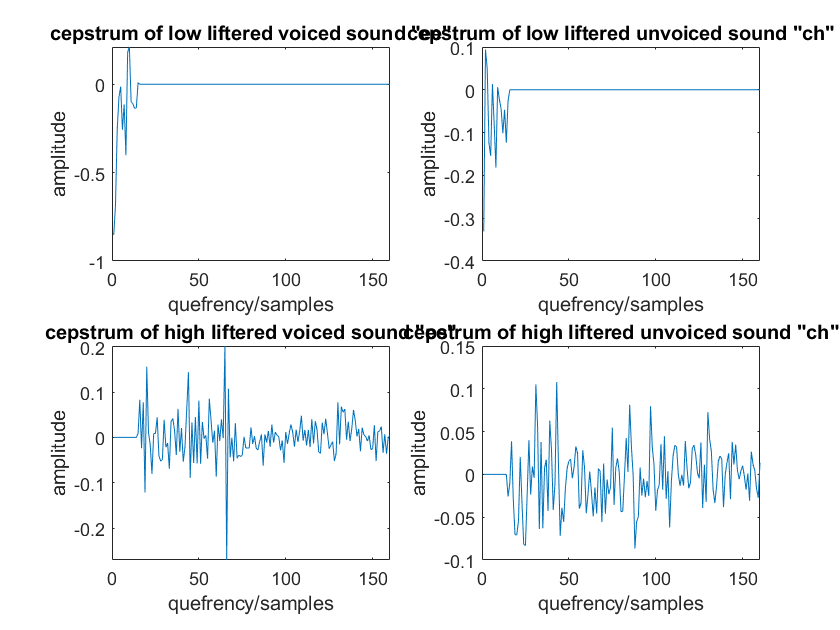

close hidden;
% VOICED PART
    % creating low pass filter
    Lc = 15;
    w_1 = zeros(1,length(cepst_voiced));
    w_1(1:Lc) = 1;
    
    % low pass liftering
    low_liftered_voiced = cepst_voiced.*w_1';
    subplot(221)
    plot(low_liftered_voiced);
    title('cepstrum of low liftered voiced sound "ee"'); xlabel('quefrency/samples'); ylabel('amplitude');
    
    % creating high pass filter
    w_2 = zeros(1,length(cepst_voiced));
    w_2(Lc:length(cepst_voiced)) = 1;
    
    % high pass liftering
    high_liftered_voiced = cepst_voiced.*w_2';
    subplot(223)
    plot(high_liftered_voiced);
    title('cepstrum of high liftered voiced sound "ee"'); xlabel('quefrency/samples'); ylabel('amplitude');
    
% UNVOICED PART    
    % creating low pass filter
    w_1 = zeros(1,length(cepst_unvoiced));
    w_1(1:Lc) = 1;
    
    % low pass liftering
    low_liftered_unvoiced = cepst_unvoiced.*w_1';
    subplot(222)
    plot(low_liftered_unvoiced);
    title('cepstrum of low liftered unvoiced sound "ch"'); xlabel('quefrency/samples'); ylabel('amplitude');
        
    % creating high pass filter
    w_2 = zeros(1,length(cepst_unvoiced));
    w_2(Lc:length(cepst_unvoiced)) = 1;
    
    % high pass liftering
    high_liftered_unvoiced = cepst_unvoiced.*w_2';
    subplot(224)
    plot(high_liftered_unvoiced);
    title('cepstrum of high liftered unvoiced sound "ch"'); xlabel('quefrency/samples'); ylabel('amplitude');

#### 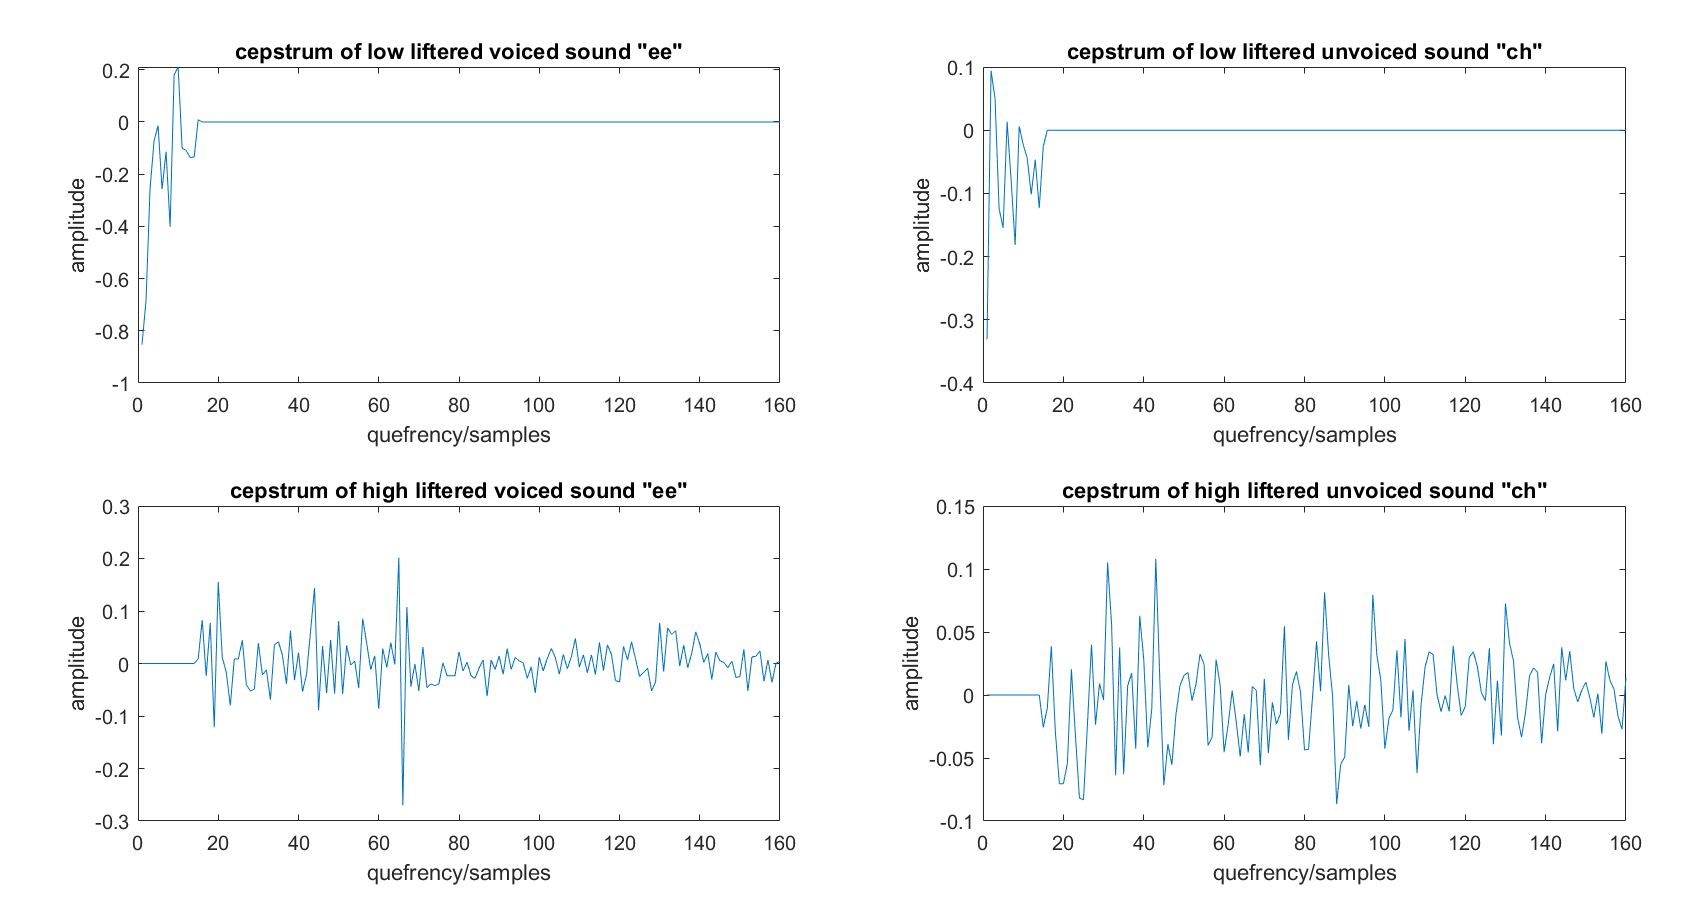

#### b.

#### Procedure/Observations:

We create a low pass filter, which will multiply the original signal by 1 until the cutoff length Lc, and we create a high pass filter, which will multiply the signal by 1 from cutoff length till the end of the signal.

The cutoff length generally chosen is from 15-20 (here i have selected 15)

To get the low pass liftered and high pass liftered cepstrum, we simply multiply original signal with these filters (element by element).

We use zeros function to create a matrix of zeros and use colon operator to insert values for a given range (for low pass, we need "1" value for 1:15, whereas for high pass, we need "1" value for 15:end)

### C. Pitch estimation by cepstral analysis: 

a. In the case of the voiced segment, estimate the pitch of the voiced speech segment using the cepstral analysis. Explain your procedure.

### Theory:

We know that the pitch information is obtained by applying high time liftering to the cepstrum. We then know that the sample number corresponding to the highest peak will represent the pitch period(after converting to time domain) of the voiced sound, hence we can easily find the pitch frequency by taking reciprocal of the pitch period. 

### Procedure:

We will find the value of the maximum peak and take the corresponding quefrency/sample associated with this peak. This will give us the pitch period, which can be used to calculate the pitch frequency.

### Code:

xIndex = find(high_liftered_voiced == max(high_liftered_voiced), 1, 'first');

pitch_pd = xIndex/fs;
pitch_f = (1/pitch_pd);

fprintf("Pitch Frequency: %.3f Hz", pitch_f);

Pitch Frequency: 246.154 Hz

**Observations:**

For voiced sound "ee", we see that the pitch frequency is 246.154 Hz.

### D. Formant estimation by cepstral analysis: 

a. Using liftered cepstrum, estimate the frequencies of the first three resonances of the vocal tract of the voiced speech frame.. Explain your procedure. Plot the log magnitude spectrum that shows the formant information (while not having the excitation information). 

b. Repeat the above for the unvoiced speech frame. 

### Theory:

Block diagram for getting the formants from cepstrum

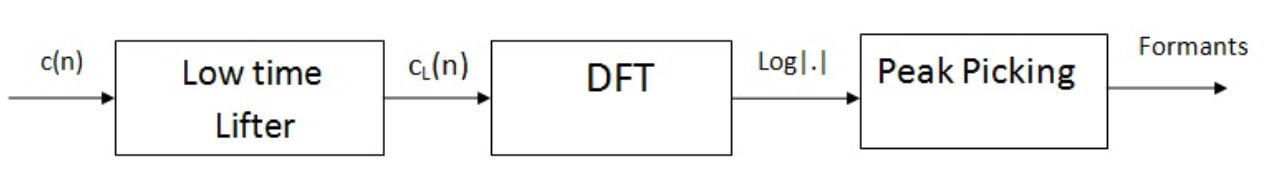

We can find the formant characteristics by analysing the vocal tract information (which we get from low time liftering the cepstrum). After applying DFT to the low time filtered cepstrum, we have to find distinguishable peaks by applying a peak picking  algorithm, thereby getting the formant characteristics of the voiced/unvoiced sounds.

### Procedure:

We apply fft to the low time liftered and high time liftered cepstrum to get the formant characteristics of the voiced/unvoiced sounds. We then use a simple peak picking algorithms and choose the suitable 3 resonances for unvoiced/voiced sounds and mark these points on the plots of the spectrum.

### Code:

close hidden;

% getting vocal tract system (v_t_s) component
v_t_s = abs(fftshift(fft(low_liftered_voiced)));
n = length(low_liftered_voiced);
v_t_s = v_t_s(ceil(n/2):end);

formant_freqs_voiced = [];

% peak picking
for l = 2 : length(v_t_s) - 1
    if v_t_s(l) > v_t_s(l-1) && v_t_s(l) > v_t_s(l+1)
        formant_freqs_voiced = [formant_freqs_voiced l];
    end
end

% taking the 3 resonances
formant_freqs_voiced = formant_freqs_voiced(3:5);

% plotting spectrum

f = fs*[-n/2:n/2-1]/n;
f = f(ceil(n/2):end);

subplot(211)
plot(f, v_t_s);
hold on
plot(f(formant_freqs_voiced),v_t_s(formant_freqs_voiced),'r*')
xlabel('Frequency (Hz)')
ylabel('Log Magnitude Spectrum');
title('Log magnitude spectrum of voiced sound "ee"');

b)

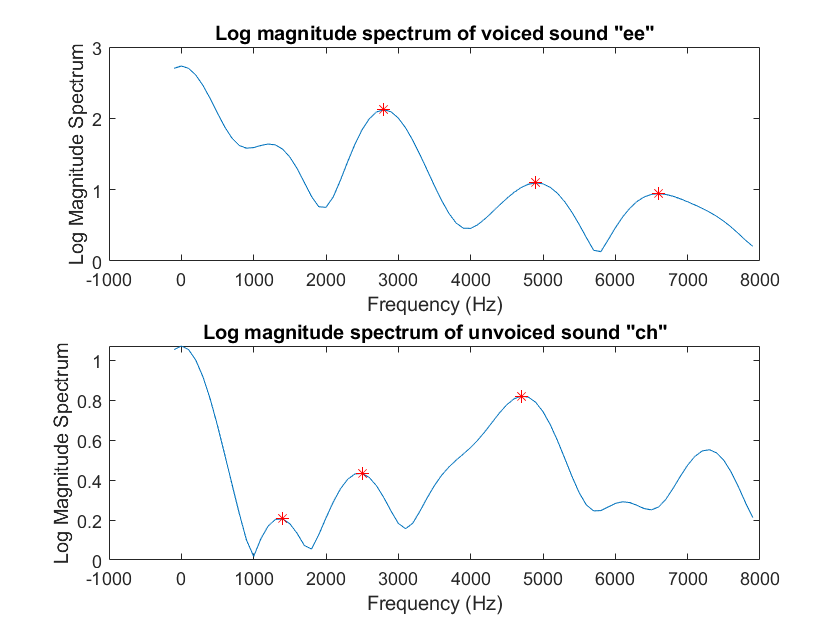

% getting vocal tract system (v_t_s) component
v_t_s = abs(fftshift(fft(low_liftered_unvoiced)));
n = length(low_liftered_unvoiced);
v_t_s = v_t_s(ceil(n/2):end);

formant_freqs_unvoiced = [];

% peak picking
for k = 2 : length(v_t_s) - 1
    if v_t_s(k) > v_t_s(k-1) && v_t_s(k) > v_t_s(k+1)
        formant_freqs_unvoiced = [formant_freqs_unvoiced k];
    end
end

% taking the 3 resonances
formant_freqs_unvoiced = formant_freqs_unvoiced(2:4);

% plotting spectrum
f = fs*[-n/2: n/2-1]/n;
f = f(ceil(n/2):end);

subplot(212)
plot(f, v_t_s);
hold on
plot(f(formant_freqs_unvoiced),v_t_s(formant_freqs_unvoiced),'r*')
xlabel('Frequency (Hz)')
ylabel('Log Magnitude Spectrum');
title('Log magnitude spectrum of unvoiced sound "ch"');

### 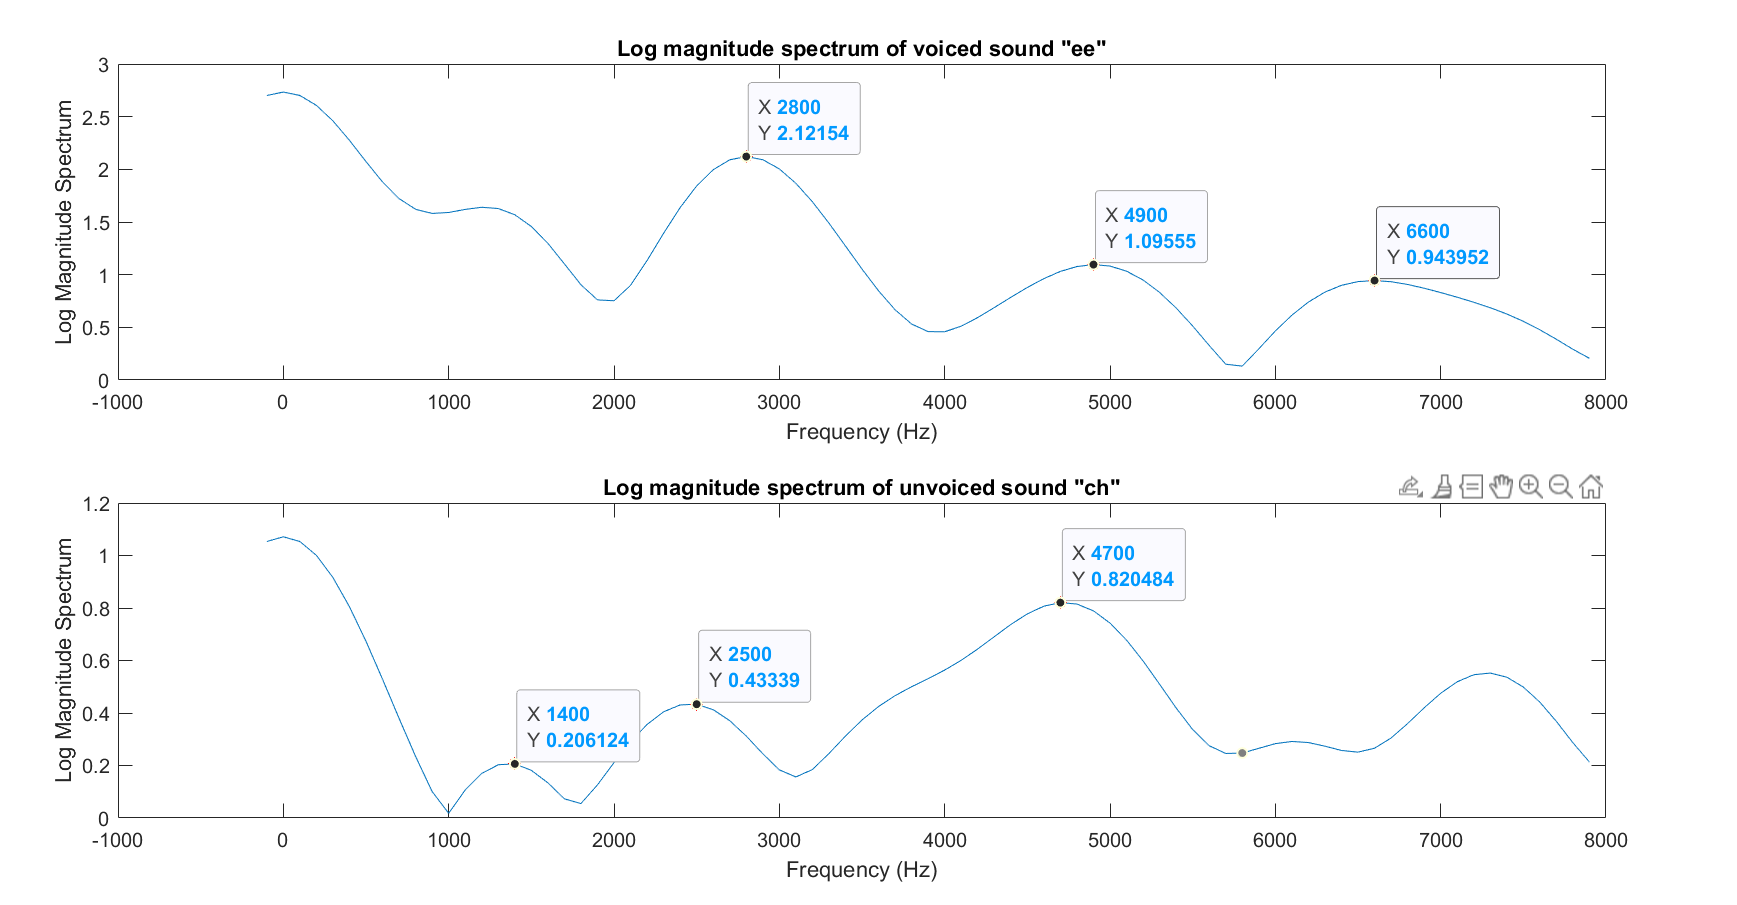

### Observations:

We observe that for unvoiced, we see an increasing slope in the resonances whereas for voiced we see a decreasing slope for the resonances.

Frequencies of the 1st three resonances are as follows:

For voiced: 2800 Hz, 4900 Hz, 6600 Hz

For unvoiced: 1400 Hz, 2500 Hz, 4700 Hz

### Function Definitions

function plot_time_signal(y, fs, title_name)  % PLOT TIME DOMAIN PLOT FOR ANY SIGNAL
    plot((0:length(y)-1)/fs,y);
    xlabel("Time");
    ylabel("Amplitude");
    title(title_name);
end

function plot_freq_spectrum(x, fs, title_name, mode)
    N = length(x);
    n = pow2(nextpow2(N)); % Transforming the length so that the number of samples is a power of 2. 
    f = fs*[0: n-1]/n;
    if strcmp(mode, 'linear')
        X_mags = (abs(fft(x, n)));
        X_mags = X_mags/n;
        y_label = 'Linear scale magnitude';
    elseif  strcmp(mode, 'log')
        X_mags = 20*log10(abs(fft(x, n)));
        y_label = 'Log scale magnitude (dB)';
    end
    N_2 = ceil(n/2);
    plot(f(1:N_2), (X_mags(1:N_2)));
    xlabel('Frequency (Hz)')
    ylabel(y_label);
    title(title_name);
end